Robot = importrobot('Robot_URDF.urdf');
showdetails(Robot)

--------------------
Robot: (6 bodies)

 Idx             Body Name      Joint Name      Joint Type             Parent Name(Idx)   Children Name(s)
 ---             ---------      ----------      ----------             ----------------   ----------------
   1                Link_1          Joint1        revolute                 Base_Link(0)   Link_2(2)  
   2                Link_2          Joint2        revolute                    Link_1(1)   Link_3(3)  
   3                Link_3          Joint3        revolute                    Link_2(2)   Link_4(4)  
   4                Link_4          Joint4        revolute                    Link_3(3)   End_Effector_1(5)  End_Effector_2(6)  
   5        End_Effector_1        Joint5_1        revolute                    Link_4(4)   
   6        End_Effector_2        Joint5_2        revolute                    Link_4(4)   
--------------------


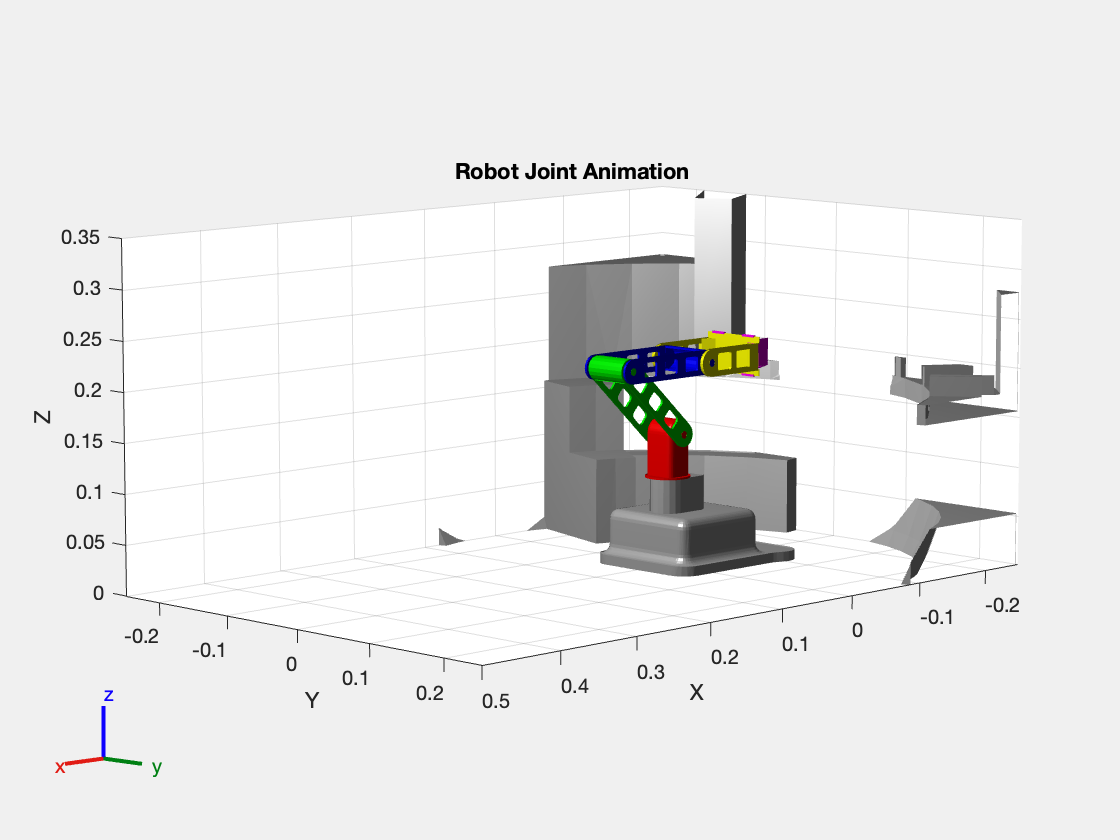


figure;
ax = axes;
show(Robot, homeConfiguration(Robot), "Frames", "off", "Parent", ax);
set(ax, 'ZLim', [0 0.35], 'XLim', [-0.25 0.5], 'YLim', [-0.25 0.25]);
title('Robot Joint Animation');


% Joint names from home configuration
config = homeConfiguration(Robot);
jointNames = {config.JointName};
numJoints = length(jointNames);

% Define joint indices for the main 4 + clamp sliders
joint1Idx = find(strcmp({config.JointName}, 'joint1'));
joint2Idx = find(strcmp({config.JointName}, 'joint2'));
joint3Idx = find(strcmp({config.JointName}, 'joint3'));
joint4Idx = find(strcmp({config.JointName}, 'joint4'));
clampLIdx = find(strcmp({config.JointName}, 'clamp_left_slider'));
clampRIdx = find(strcmp({config.JointName}, 'clamp_right_slider'));

angleSteps = 60;
angleRange = 0:angleSteps:360;

% Clamp motion range (e.g. ±0.02 m)
clampRange = linspace(-0.02, 0.02, length(angleRange));

for i = 1:length(angleRange)
    joint1Angle = angleRange(i);
    for joint2Angle = angleRange
        for joint3Angle = angleRange
            for joint4Angle = angleRange
                config = homeConfiguration(Robot);

                config(joint1Idx).JointPosition = deg2rad(joint1Angle);
                config(joint2Idx).JointPosition = deg2rad(joint2Angle);
                config(joint3Idx).JointPosition = deg2rad(joint3Angle);
                config(joint4Idx).JointPosition = deg2rad(joint4Angle);

                % Clamp sliders move in opposite directions
                clampPos = clampRange(i);
                config(clampLIdx).JointPosition = clampPos;
                config(clampRIdx).JointPosition = -clampPos;

                show(Robot, config, "Frames", "off", "Parent", ax);
                set(ax, 'ZLim', [-0.2 0.35], 'XLim', [-0.4 0.5], 'YLim', [-0.4 0.4]);
                
                drawnow;
                pause(0.5);
            end
        end
    end
end

Assigning to 0 elements using a simple assignment statement is not supported. Consider using comma-separated list assignment.

Related documentation